# demographics of jellyfish by hosts

## load data

global DEFAULT_MATFILE_DIR
load([ DEFAULT_MATFILE_DIR '\jf_statsByHosts_CJF.mat']);


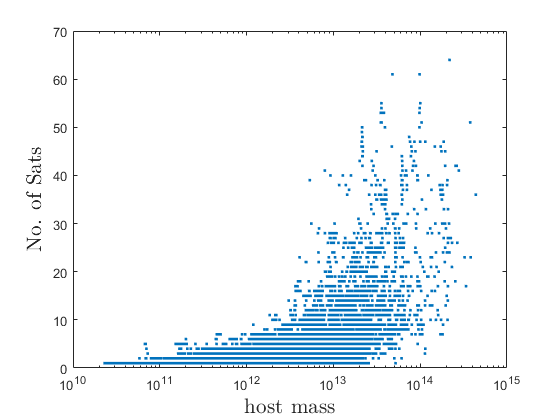

figure
semilogx(jfStats.M200c,jfStats.sampleSats,'.');
xlabelmine('host mass');
ylabelmine('No. of Sats');

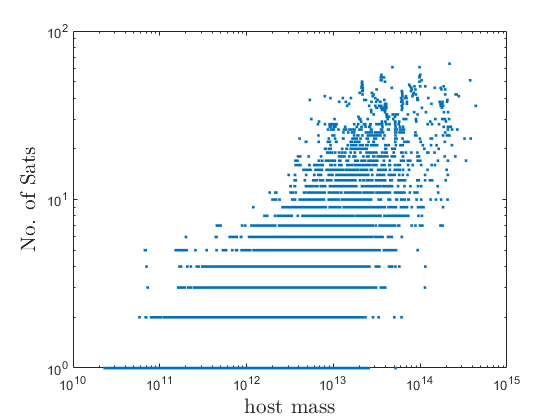


figure
loglog(jfStats.M200c,jfStats.sampleSats,'.');
xlabelmine('host mass');
ylabelmine('No. of Sats');

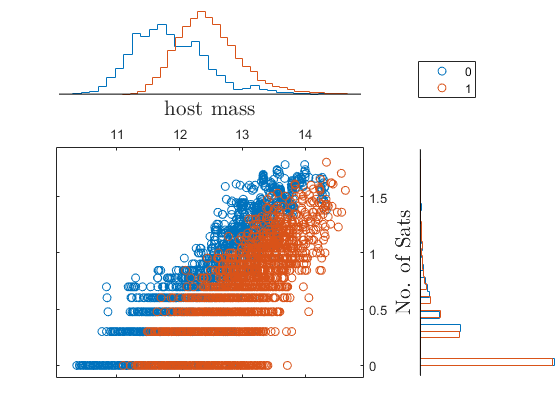


figure
scatterhist(log10(jfStats.M200c),log10(jfStats.sampleSats),...
    'group',jfStats.sim=="TNG100",...
    'location','northeast','Direction','out','kernel','off',...
    'nbins',30);
xlabelmine('host mass');
ylabelmine('No. of Sats');

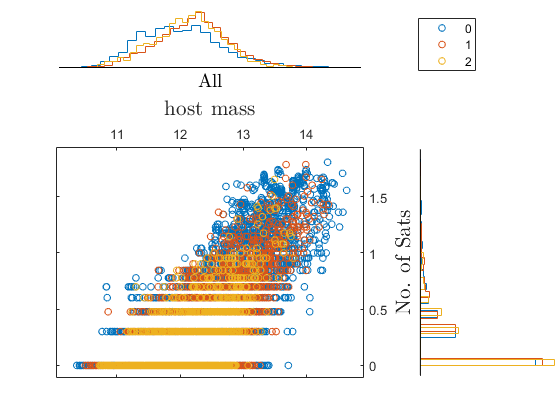

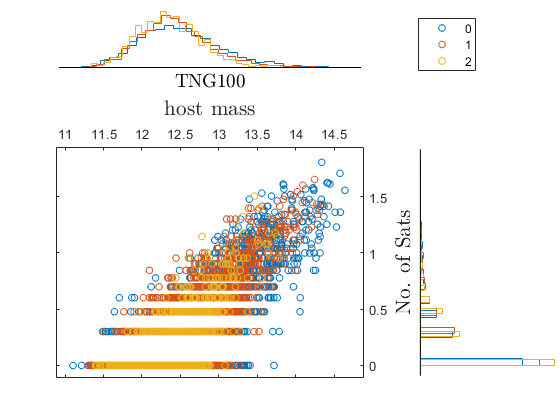

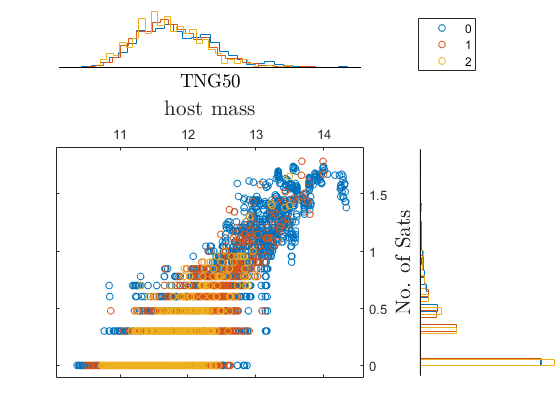

zr=illustris.utils.snap2redshift(jfStats.snap);
gr=ones(size(zr));
gr(zr<=0.5)=0;
gr(zr>0.5 & zr<=1)=1;
gr(zr>1 & zr<=2)=2;

for j=1:3
    switch j
        case 1
            msk=true(size(jfStats.sim));
            tit='All';
        case 2 
            msk=jfStats.sim=="TNG100";
            tit='TNG100';
        case 3
            msk=jfStats.sim=="TNG50";
            tit='TNG50';

    end

figure
scatterhist(log10(jfStats.M200c(msk)),log10(jfStats.sampleSats(msk)),...
    'group',gr(msk),...
    'location','northeast','Direction','out','kernel','off',...
    'nbins',30,'markersize',5);
xlabelmine('host mass');
ylabelmine('No. of Sats');
titlemine(tit);
end

## plot jf fractions

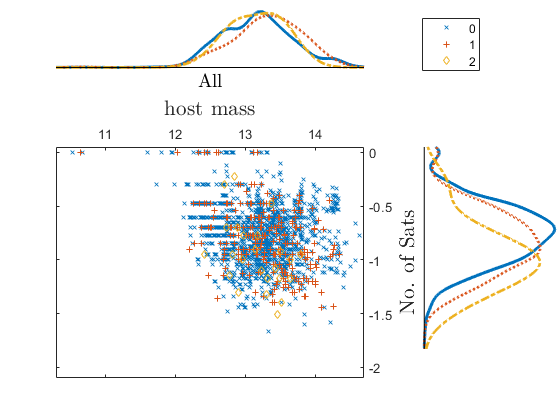

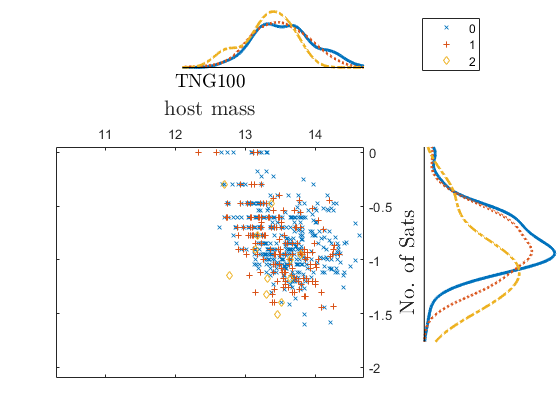

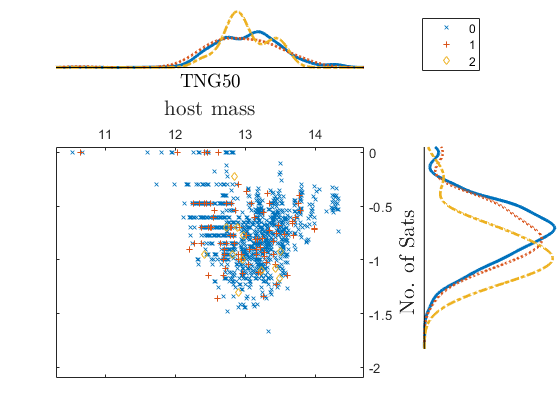

zr=illustris.utils.snap2redshift(jfStats.snap);
gr=ones(size(zr));
gr(zr<=0.5)=0;
gr(zr>0.5 & zr<=1)=1;
gr(zr>1 & zr<=2)=2;

jff=jfStats.JFNum./jfStats.sampleSats;

% give fictitios frac for zero 
base=1e-2;
scat=0.2;
mmm=jff==0;
jff(mmm)=base.*10.^(scat.*rand(1,sum(mmm)));


for j=1:3
    switch j
        case 1
            msk=true(size(jfStats.sim)) ;
            tit='All';
        case 2 
            msk=jfStats.sim=="TNG100"  ;
            tit='TNG100';
        case 3
            msk=jfStats.sim=="TNG50"  ;
            tit='TNG50';

    end

    mskk=msk & ~mmm;
figure
scatterhist(log10(jfStats.M200c(mskk)),log10(jff(mskk)),...
    'group',gr(mskk),...
    'location','northeast','Direction','out','kernel','on',...
    'nbins',20,'markersize',4,'marker','x+d');
% hold on
% plot(log10(jfStats.M200c(msk & mmm)),log10(jff(msk & mmm)),'.')
xlim([10.3 14.7])
ylim([-2.1 0.05])
xlabelmine('host mass');
ylabelmine('No. of Sats');
titlemine(tit);
end

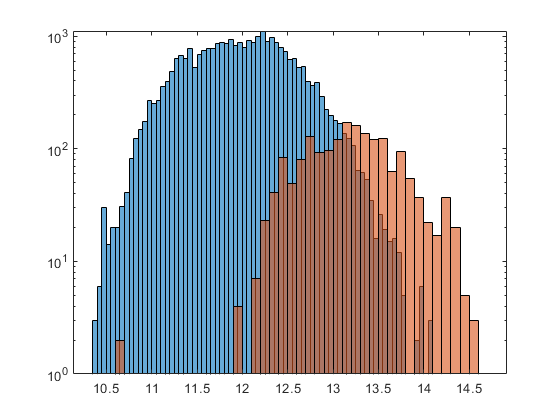


figure
histogram(log10(jfStats.M200c(mmm)));
hold on;
histogram(log10(jfStats.M200c(~mmm)))
set(gca,'yscale','log')